# ** MEC3079S: Control Systems**

# Chapter 3 — Block diagrams

## 3.1 Introduction

We have been working with individual subsystems represented by a block with its input and output. More complicated systems, however, are represented by the interconnection of many subsystems. Since the response of a single transfer function can be calculated, we want to represent multiple subsystems as a single transfer function. We can then apply the analytical techniques of the previous chapters and obtain transient response information about the entire system.

As you already know, a subsystem is represented as a block with an input, an output, and a transfer function. Many systems are composed of multiple subsystems.

## 3.2 Block diagram components

Block diagrams for linear, time-invariant systems consists of four types of components:

- **Signals** — denoted as arrows, where the arrowhead indicates direction of signal flow.

- **Systems** — denoted by blocks. 

- **Summing junctions **— denoted with a circle, and relevant signs.

- **Pickoff point **— a signal that branches off in multiple directions.

### 3.2.1 Signals

**Signals **are denoted with arrows, with the arrowhead indicating the direction in which the signal is flowing. Each signal can represented either in the time domain, such as $u(t)$, or in the Laplace domain, such as $U(s)$. Signals are quantities that we can usually measure (if we have the appropriate sensors) or set directly (if we are the ones controlling the signal). Signals entering a system (with the arrowhead pointing towards the system) are known as the system's input, whereas signals exiting a system (with the arrowhead pointing away from the system) are known as the system outputs.

### 3.2.2 Systems

**Systems **are represented with blocks. These are quantities that we cannot measure directly. Although, we can infer the value of the system if we are able to measure both the input and output of the system. The system block defines the *mapping *from an input signal to an output signal. As shown below, $U(s)$ is an input to system $P(s)$, with $Y(s)$ the corresponding output.

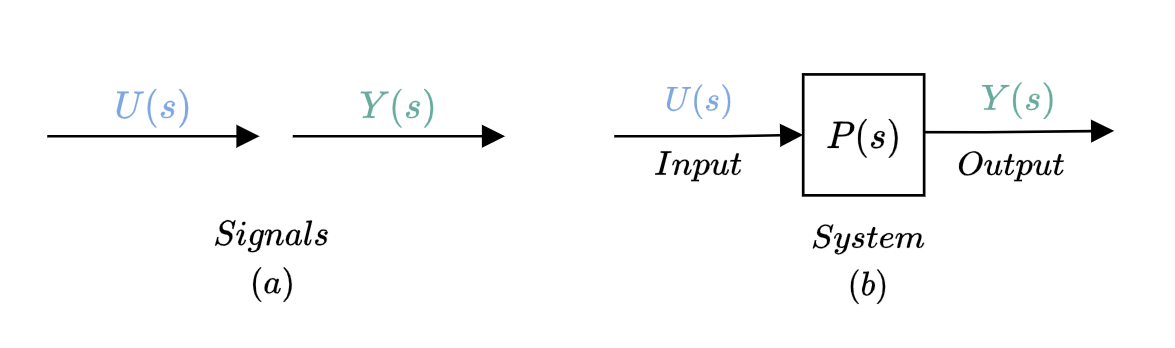

Based on our understanding of transfer functions from the previous chapter, we can then determine from the above figure that 

$Y(s)=P(s)U(s)$.

We can therefore determine system blocks as representing mulitplication in the Laplace domain. In other words, the system output, $Y(s)$, is equal to the product of the system, $P(s)$, and input, $U(s)$. It then follows that

$P(s)=\frac{Y(s)}{U(s)}$.

### 3.2.3 Summing junctions

**Summing junctions** are a means of representing the addition and/or subtraction of multiple signals. The *sign* attached to the particular signal indicates whether the operation is addition or subtraction, and the output of the summing junction is the algebraic sum of all signals, after taking into account the relevant signs.

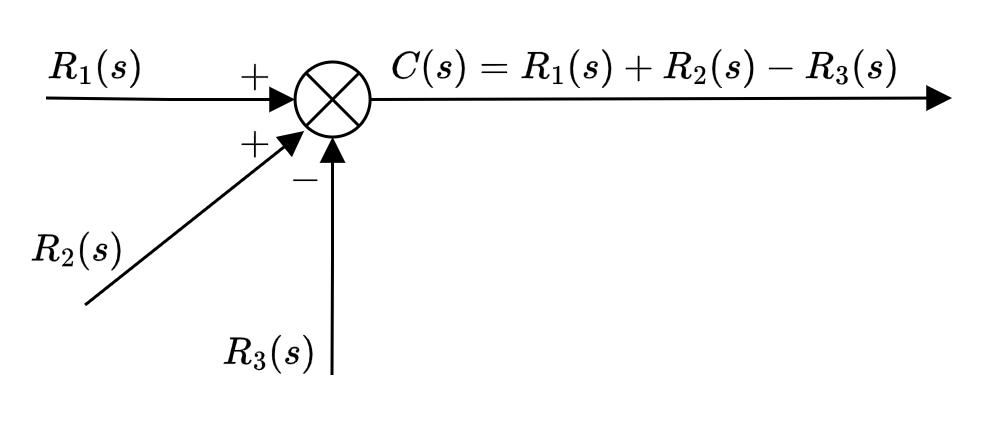

Based on the above figure, the output of the summing junction is

$C(s)=R_1(s)+R_2(s)-R_3(s)$.

The example above shows three inputs, but any number of inputs can be present, with any arbitrary combination of signs.

### 3.2.4 Pickoff point

A **pickoff point** is used to distribute a common signal to multiple destinations, without altering its value.

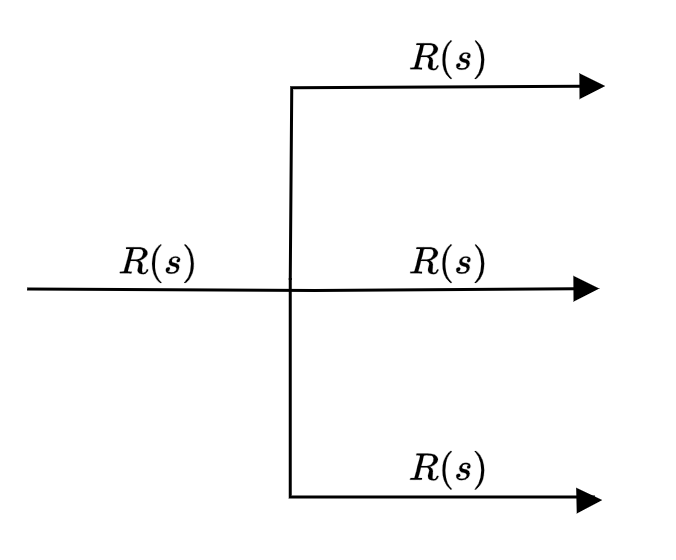

You can think of the lines of the signal as a wire: every point along that wire, the same "potential" or "voltage" exists, as it is still one signal, albeit distributed in multiple directions. Any number of splittings can occur without loss of generality.

## 3.3 Block diagram topologies

We will focus on three predominant block diagram topologies, namely:

- Cascade (series) form

- Parallel form

- Feedback form

### 3.3.1 Cascade form

When modelling in the Laplace domain, we already know that signals and systems interact in a multiplicative sense. That is, the system output, $Y(s)$, is equal to the product of the system model, $P(s)$, and input signal, $U(s)$

$Y(s)=P(s)U(s)$.

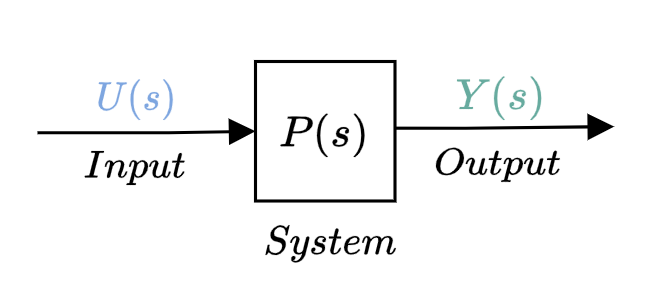

If we use the relationship above, this result can be generalised to any number of signals and systems, as shown below.

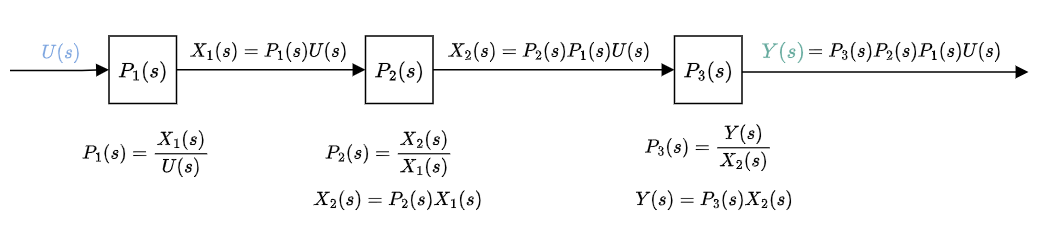

This interconnection of subsystems in *series* is known as **cascade form**. The equivalent transfer function $P_c(s)=Y(s)/U(s)$ follows as

$P_c(s)=P_1(s)P_2(s)P_3(s)$,

as shown below

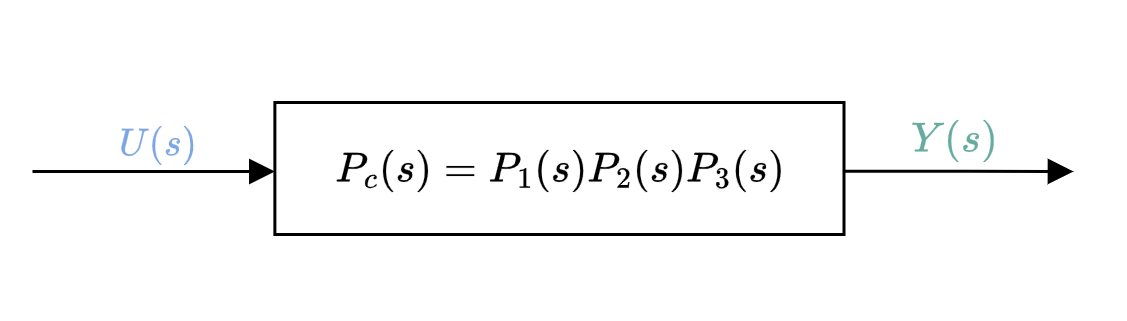

Importantly, this only applies to systems where interconnecting subsystems does not *load* adjacent subsystems. That is, a subsystem's output remains the same whether or not the subsequent subsystem is connected. This is often problematic in electrical networks, but a buffer can be placed between interconnecting subsystems to circumvent this issue. Unless otherwise stated, we will assume in this course that there are no loading issues in our system models.

In `MATLAB` we can evaluate this by simply multiplying each system

%Example
s = tf('s');
P1 = 1/s;
P2 = 5;
P3 = 1/(1+s);

Pc = P1*P2*P3

Pc =
 
     5
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


### 3.3.2 Parallel form

When multiple subsystems have a common input and sum their respective outputs at a summing junction, this is know as a **parallel form**. With reference to the image below, if we algebraically determine each subsystem output, we can determine that the resulting output, $Y(s)$, is a product of the common input, $U(s)$, and equivalent transfer function $P_p(s)$, 

$Y(s)=P_p(s)U(s)$,

where 


$$P_p(s)=\pm P_1(s)\pm P_2(s)\pm P_3(s)$$


is the sum of all parallel subsystems, after taking into account the signs at the summing junction.

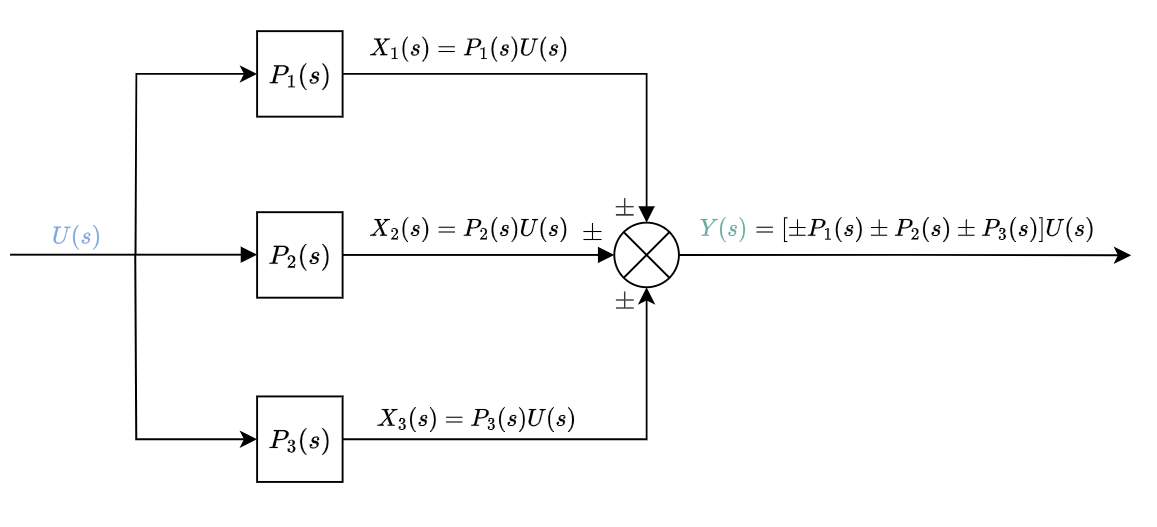

In `MATLAB` we can evaluate this by simply summing each system

%Example
s = tf('s');
P1 = 1/s;
P2 = 5;
P3 = 1/(1+s);

Pp = P1+P2+P3

Pp =
 
  5 s^2 + 7 s + 1
  ---------------
      s^2 + s
 
Continuous-time transfer function.
Model Properties


### 3.3.3 Feedback form

The feedback topology forms the basis for our study of closed-loop control systems engineering (although we will only go into detail later in the course!). With reference to the figure below, the output and error are related by

$Y(s)=L(s)E(s)$.

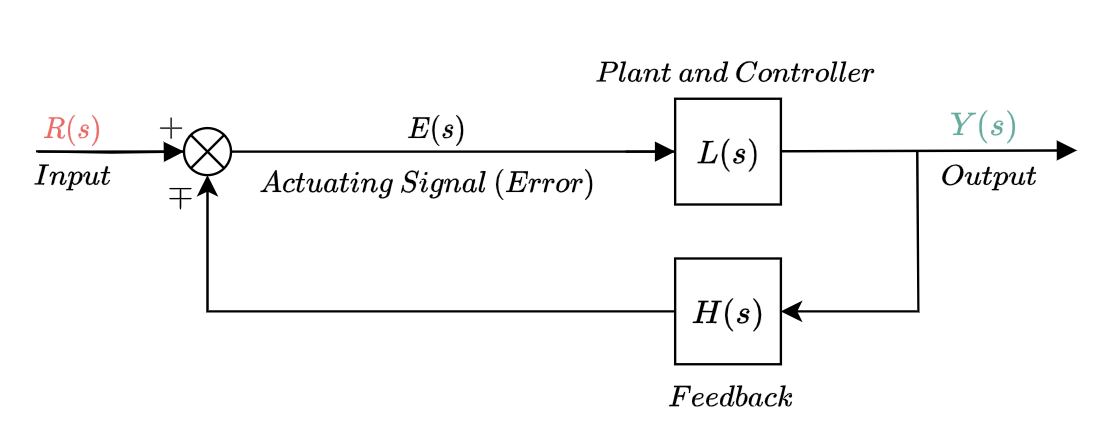

Referring to the summing junction, we know that 

$E(s)=R(s) \mp H(s)Y(s)$.

We can then substitute this equation into the previous equation to get

$Y(s)=L(s)\left[R(s)\mp H(s)Y(s)\right]$.

We can then rearrange this equation to ultimately find the transfer function of $Y(s)/R(s)$:

$\frac{Y(s)}{R(s)}=T_e(s)=\frac{L(s)}{1\pm L(s)H(s)}$.

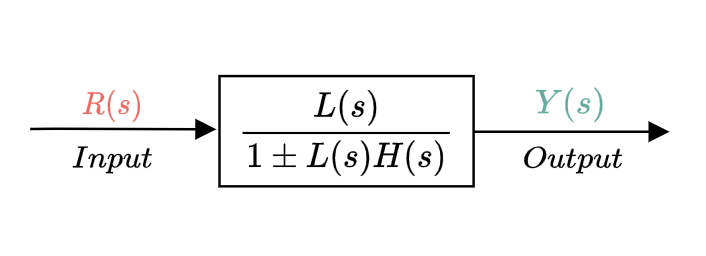

The structure above is known as **feedback **(or **closed-loop**) **form**, as we have "closed the loop" from output back to plant input. The system is said to have *negative feedback* if the sign at the summing junction is negative and *positive feedback* if the sign is positive. 

The **loop transfer function** is $L(s)H(s)$, which describes the product of subsystems within the loop (from the signal exiting the summing junction to the signal reentering the summing junction.

The above result generalises for both positive and negative feedback, but we will predominantly work with a simplified form of negative feedback, with $H(s)=1$, which takes the form

$\frac{Y(s)}{R(s)}=T(s)=\frac{L(s)}{1+ L(s)}$.

Here $T(s)$ refers to the complementary sensitivity function, which will be instrumental in how we analyse and design our feedback controller — more on this later!

In `MATLAB` we can evaluate the feedback form using the `feedback` function, which assumes negative feedback (although you can change this by adjusting the sign of the second term). We can also equivalently write out `L/(1+L*H) `in code.

%Example
s = tf('s');
L = 1/s;
H = 1/(1+s/10);

Te = feedback(L,H)

Te =
 
      s + 10
  ---------------
  s^2 + 10 s + 10
 
Continuous-time transfer function.
Model Properties


Note that if we want positive feedback we can change the sign of $H$.

## 3.4 Block diagram reduction

the familiar forms (cascade, parallel, and feedback) are not always apparent in a block diagram. For example, in the feedback form, if there is a pickoff point after the summing junction, you cannot use the feedback formula to reduce the feedback system to a single block. That signal disappears, and there is no place to reestablish the pickoff point.

We will, at times, first need to manipulate a block diagram before we can make use of our common topologies to reduce a complex block diagram. Importantly, any manipulation and reduction must *not* distort the input-output signal relationship.

### 3.4.1 Equivalent forms of summing junctions

Systems can be moved over summing junctions as long as the signal descriptions remain constant. With reference to the figure below, we can move $P(s)$ "backwards" (or "leftwards") over the summing junction, which places a $P(s)$ system block on both signal paths that enter the summing junction. 

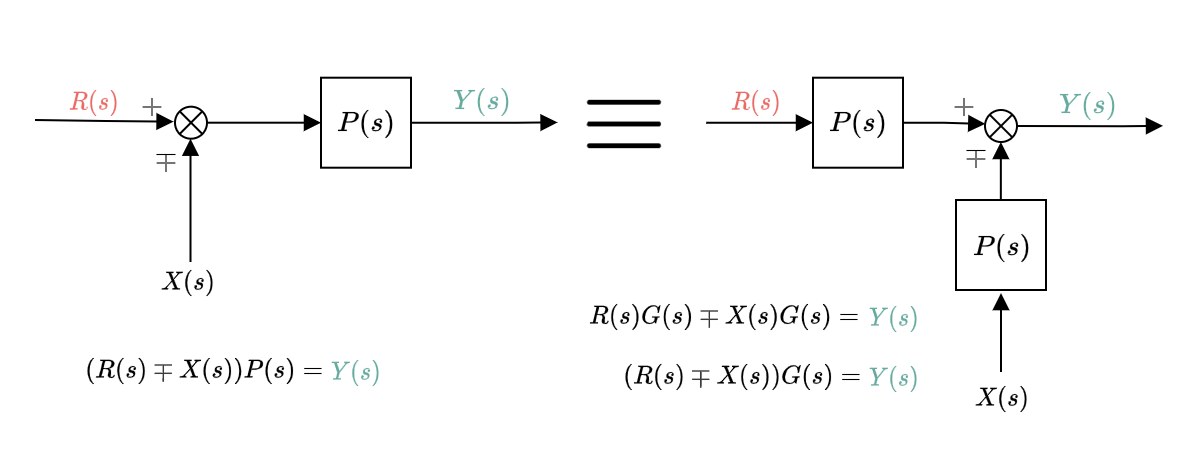

Note that the equation for $Y(s)$ remains unchanged as


$$\begin{array}{rl}
Y(s)
&=R(s)P(s)\mp X(s)P(s),\\ 
&=P(s)\left[R(s)\mp X(s). \\
\end{array}$$


With reference to the figure below, we can similarly move $P(s)$ "forwards" (or "rightwards") over the summing junction, but any signals entering the summing junction must then be multiplied by the inverse of $P(s)$.

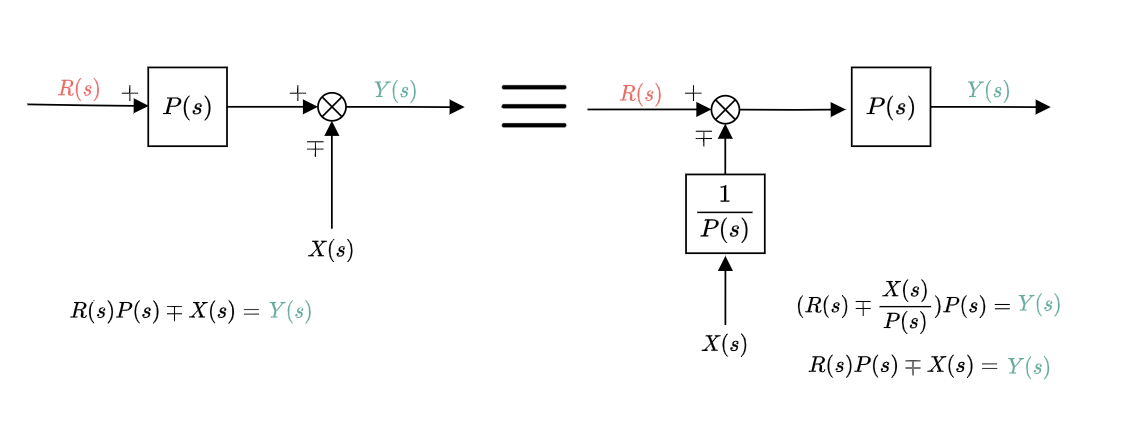

As before, the output remains as

$\begin{array}{rl}
Y(s)
&=P(s)[R(s)\mp \frac{X(s)}{P(s)}]P(s)\\
&=P(s)R(s)\mp X(s)\\
\end{array}$.

In each diagram, the equivalence can be verified by tracing the signals at the input through to the output and recognizing that the output signals are identical. If the input-output mappings are not identical, then a mistake has been made.

### 3.4.2 Equivalent forms of pickoff points

With reference to the image below, $P(s)$ can be moved before the pickoff point, but the signals that result from the pickoff must be divided by $P(s)$ in order for the output signals to remain unchanged.

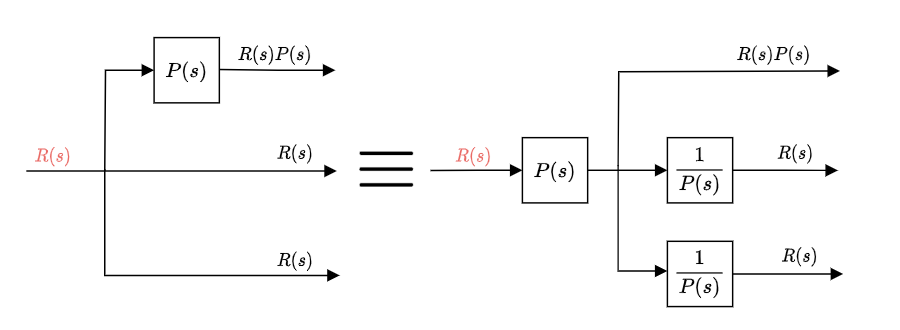

Looking at the figure below, $P(s)$ can be moved after the pickoff point, which requires each pickoff signal to be multiplied by $P(s)$.

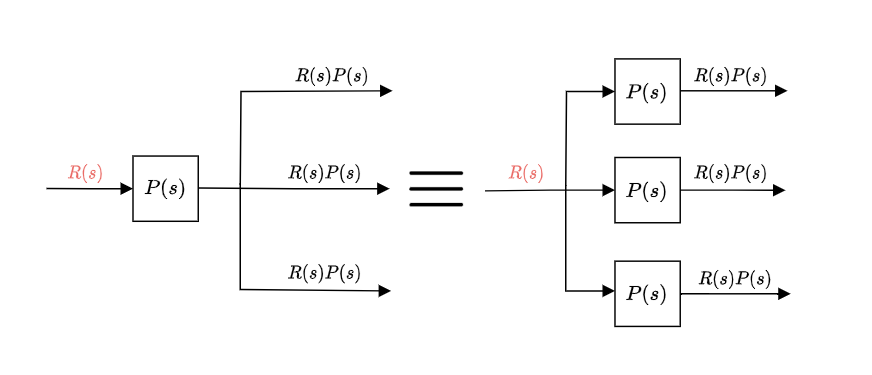

In both cases, each signal output is left unchanged, which shows that the equivalent form has not altered the input-output relationships.

### 3.4.3 Reduction using familiar forms

We can use our knowledge of the various topologies and equivalent forms to manipulate and reduce complex block diagrams to a single transfer function of $Y(s)=T_e(s)R(s)$.

#### Example 1

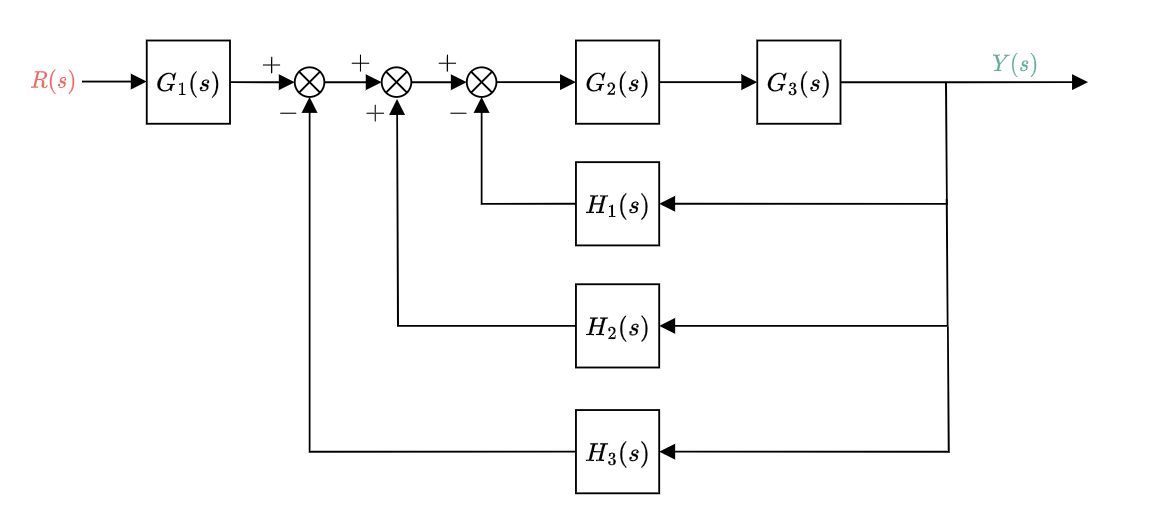

Referring to the example above, we can take the following steps (there are often multiple ways to reduce a block diagram) to find $T_e(s)$:

**(a) **Collapse summing junctions to a single summing junction.

**(b) **Form equivalent cascaded system in the forward path and equivalent parallel system in the feedback path.

**(c) **Form equivalent feedback system and multiply by cascaded

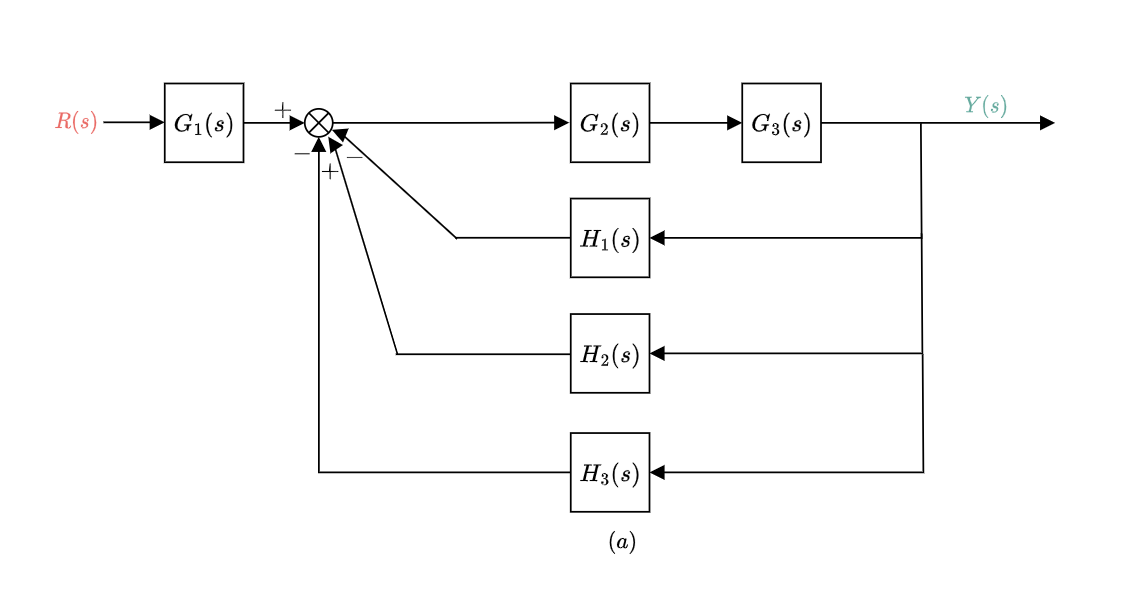

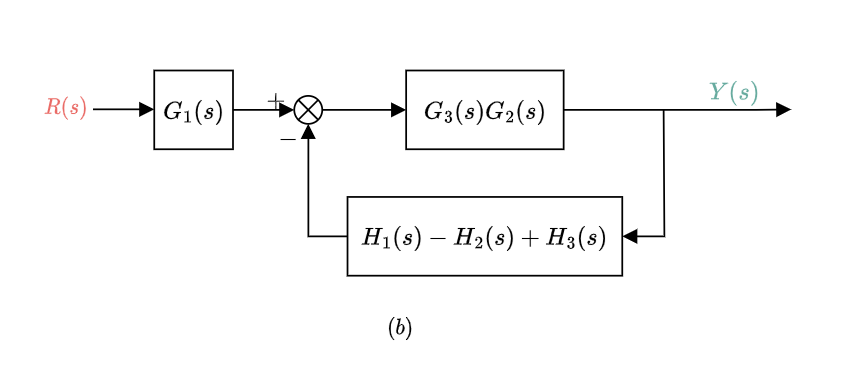

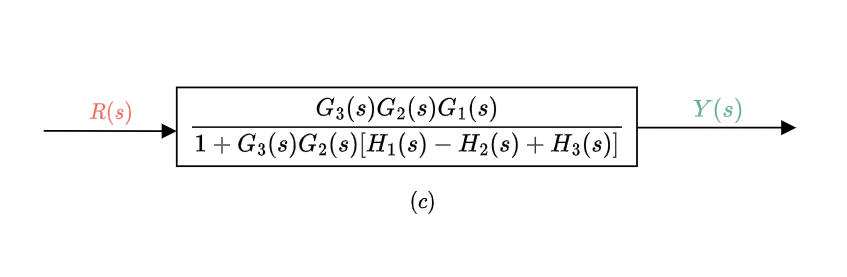

Note that we could have repeatedly used our feedback form reduction, but this would have resulted in a number of ratios of transfer functions, which can easily lead to mistakes when resolving. In other words, there are often multiple ways to perform the block diagram reduction, but some are more "efficient" than others.

#### Example 2

Consider the block diagram below.

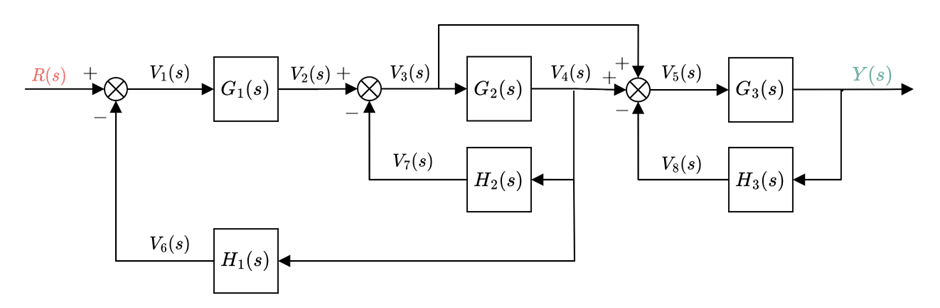

We can take the following steps to determine $Y(s)/R(s)=T_e(s)$:

**(a) **Move $G_2(s)$ backwards past the pickoff point. This allows us to reduce the feedback system of $G_3(s)H_3(s)$, as well as define a parallel system after $V_4(s)$.

**(b) **Simplify the parallel system after $V_4(s)$ and move $G_1(s)$ forwards over the summing junction.

**(c) **Collapse the summing junctions, sum the parallel feedback elements, and simplify the cascaded subsystems.

**(d) **Simplify the feedback structure.

**(e) **Simplify the resulting cascaded form to a single transfer function.

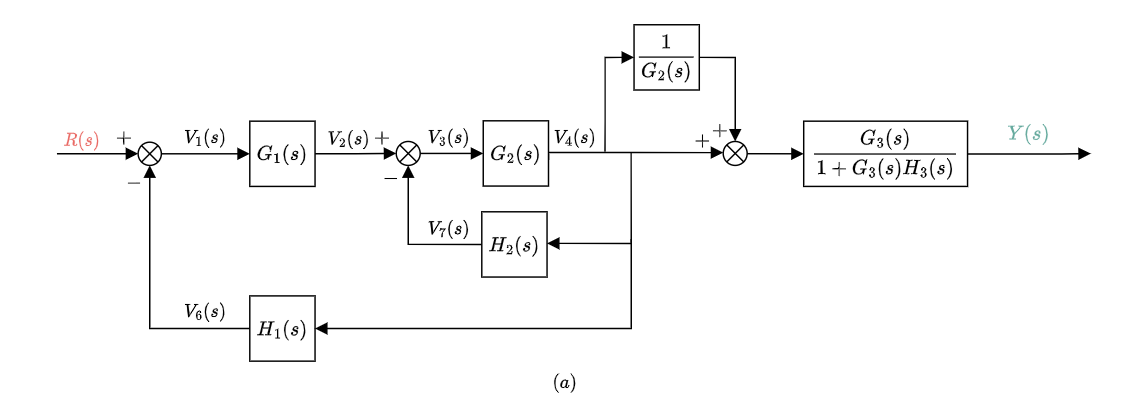

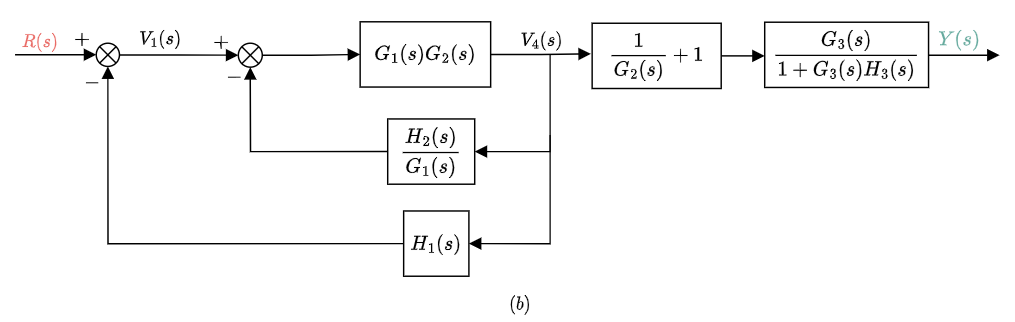

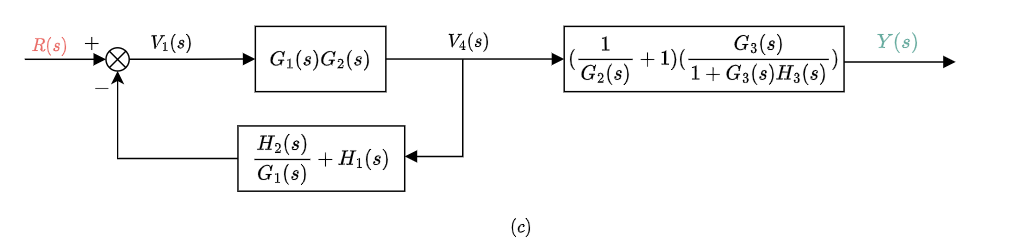

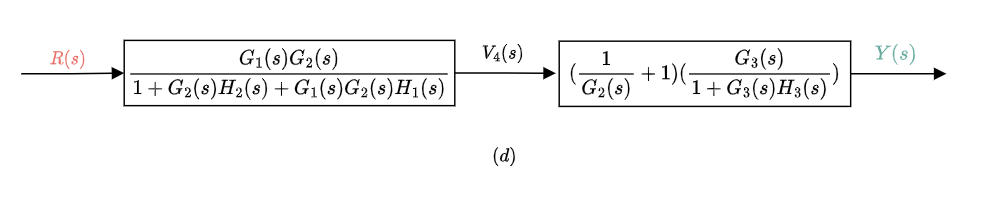

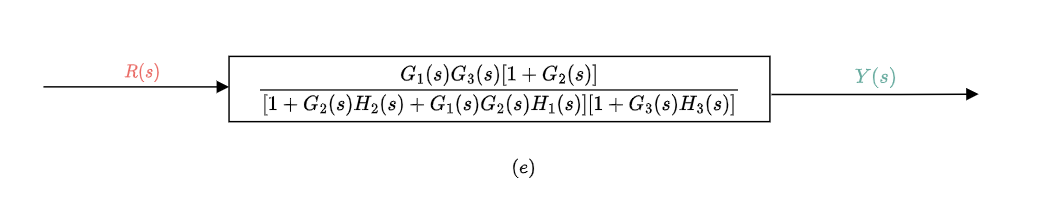

## 3.5 Determining closed-loop transfer behaviour from block diagrams

### 3.5.1 Transfer behaviour from external signals

Consider the system below. Contrary to the previous example, we now have multiple external (exogenous) signals that enter the system, namely $R(s)$, $D(s)$, and $N(s)$. 

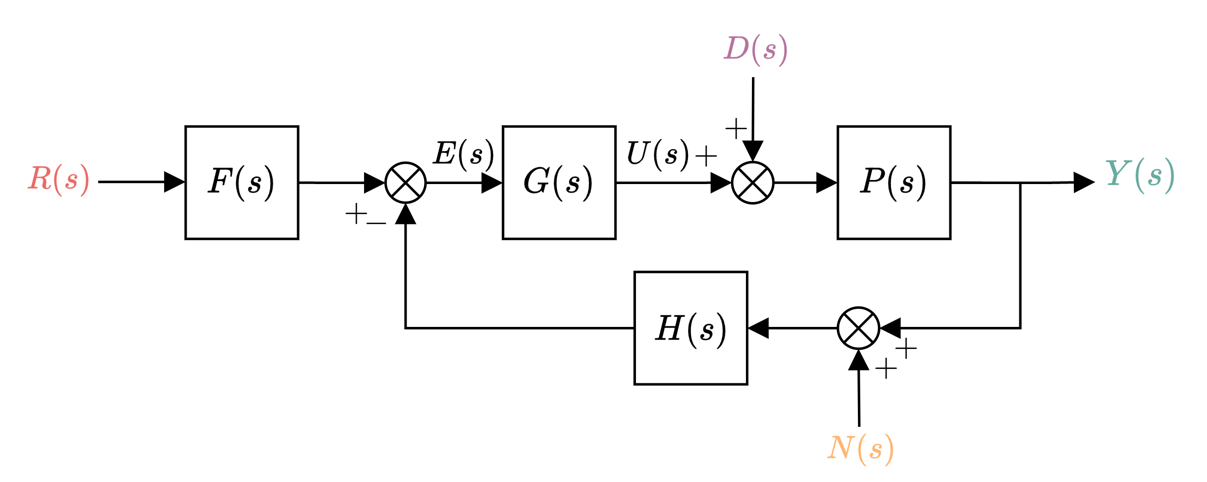

We begin by calculating $Y(s)$, which will end up depending on all external signals, as well as the various system blocks in the system. Using first principles, we can determine $Y(s)$ as


$$\begin{array}{rl}
Y(s)
&= P(s)[D(s)+U(s),]\\
&= P(s)[D(s)+G(s)E(s)],\\
&= P(s)[D(s)+G(s)F(s)R(s)-G(s)H(s)N(s)-G(s)H(s)Y(s)],\\
\end{array}$$


where


$$\begin{array}{rl}
E(s)
&= F(s)R(s)-H(s)N(s)-H(s)Y(s).\\
\end{array}$$


We then group the $Y(s)$ terms as


$$\begin{array}{rl}
Y(s)[1+P(s)G(s)H(s)]
&= P(s)[D(s)+G(s)F(s)R(s)-G(s)H(s)N(s)],\\
\end{array}$$


and then solve for the output


$$\begin{array}{rl}
Y(s)
&= \frac{P(s)[D(s)+G(s)F(s)R(s)-G(s)H(s)N(s)}{1+P(s)G(s)H(s)},\\
&= \frac{P(s)}{1+P(s)G(s)H(s)}D(s)+\frac{P(s)G(s)F(s)}{1+P(s)G(s)H(s)}R(s)-\frac{P(s)G(s)H(s)}{1+P(s)G(s)H(s)}N(s).\\
\end{array}$$


Based on the above, we can infer that that the contribution of $R(s)$ to $Y(s)$ is determined by $\frac{P(s)G(s)F(s)}{1+P(s)G(s)H(s)}$, whereas the contributions of $D(s)$ and $N(s)$ are determined by $\frac{P(s)}{1+P(s)G(s)H(s)}$ and $\frac{-P(s)G(s)H(s)}{1+P(s)G(s)H(s)}$, respectively. We refer to these contributions as the **closed-loop transfer behaviour**. Note that we can determine the transfer behaviour from an external signal to $Y(s)$ by simply consulting the equation for $Y(s)$ above and then setting the other external signals to zero. For example, when $D(s)=N(s)=0$, the output is described as


$$\begin{array}{rl}
Y_R(s) 
&= \lim_{D(s),N(s)\rightarrow0} Y(s) \\
&= \lim_{D(s)\rightarrow0} \frac{P(s)}{1+P(s)G(s)H(s)}D(s)+\frac{P(s)G(s)F(s)}{1+P(s)G(s)H(s)}R(s)-\lim_{N(s)\rightarrow0}\frac{P(s)G(s)H(s)}{1+P(s)G(s)H(s)}N(s).\\
&= \frac{P(s)G(s)F(s)}{1+P(s)G(s)H(s)}R(s).
\end{array}$$


Another way to construct the signal behaviour is to consider the individual contribution from each external signal to $Y(s)$. Once each individual contribution has been calculated, the resulting $Y(s)$ is then made up of the sum of each individual amount. This is known as **superposition **and is related to the linearity property of transfer functions. Specifically, we can find the transfer behaviour from any one external signal to the output signal by first setting the other external signals to zero, followed by resolving the transfer behaviour either using first principles or block diagram reduction. 

We can determine the transfer behaviour of $R(s)$ to $Y(s)$ by first setting $D(s)=N(s)=0$. Using the feedback form from before (and assuming that we had not already generated the results from above), we can then deduce that the transfer behaviour from $R(s)$ to $Y(s)$ is

$\left. \frac{Y(s)}{R(s)}\right|_{N(s)=D(s)=0}=F(s)\frac{P(s)G(s)}{1+P(s)G(s)H(s)}$.

$\left.\frac{Y(s)}{N(s)}\right|_{R(s)=D(s)=0}$ and $\left.\frac{Y(s)}{D(s)}\right|_{R(s)=N(s)=0}$ can be calculated in a similar manner. Once we have all terms, we can then summate the results after multiplying by the relevant external signal to calculate $Y(s)$:

$Y(s)=\left. \frac{Y(s)}{R(s)}\right|_{N(s)=D(s)=0}R(s)+\left.\frac{Y(s)}{N(s)}\right|_{R(s)=D(s)=0}N(s)+\left.\frac{Y(s)}{D(s)}\right|_{R(s)=N(s)=0}D(s)$.

We have chosen $Y(s)$ as our signal of interest in the derivations above, but we could also choose any other internal signal, such as $U(s)$. Regardless of the signal, we can follow the same procedure to arrive at our answer.

### 3.5.2 Loop transfer function

The (open) **loop transfer function** is defined as the product of transfer function around the entirety of the feedback loop, starting from the output of the summing junction at $E(s)$ until the feedback loop re-enters the summing junction. In the case of the system above, this is equal to $P(s)G(s)H(s)$, ignoring the sign change at the summing junction. Note that, by no coincidence, all transfer behaviours above a common denominator of $1+P(s)G(s)H(s)$.

### 3.5.3 Forward transfer function

We describe the **forward transfer function** as the transfer behaviour between the two signals of interest assuming the feedback loop had been broken. However, for closed-loop transfer behaviour from an external signal, the forward transfer function is calculated by again replacing summing junctions with the appropriate gain. For example the forward transfer function from $R(s)$ to $Y(s)$ is $P(s)G(s)F(s)$, and the forward transfer function from $N(s)$ to $Y(s)$ is $-P(s)G(s)H(s)$.

Using our definitions of loop transfer function and forward transfer function, and consulting the respective closed-loop transfer behaviours, we can deduce that any closed-loop transfer behaviour can be determined by

$T_{cl}=\frac{\text{forward transfer function}}{1+\text{open-loop transfer function}}$.

This is easily confirmed by looking at the transfer functions of $\left. \frac{Y(s)}{R(s)}\right|_{N(s)=D(s)=0}$, $\left.\frac{Y(s)}{N(s)}\right|_{R(s)=D(s)=0}$ and $\left.\frac{Y(s)}{D(s)}\right|_{R(s)=N(s)=0}$. The equation is useful to quickly determine closed-loop transfer behaviour without having to use block diagram algebra. However, we may still need to use block diagram reduction in order to reduce a complicated block diagram into the simplified form above.

#### Example

*Determine the closed-loop transfer behaviour from *$R(s)$ to $U(s)$.

The forward transfer function from $R(s)$ to $U(s)$ is $G(s)F(s)$, and the loop transfer function is $P(s)G(s)H(s)$. Therefore, based on the formula above

$\frac{U(s)}{R(s)}=\frac{G(s)F(s)}{1+P(s)G(s)H(s)}$.

### 3.5.4 Transfer behaviour between internal signals

The transfer behaviour between two internal signals is described solely by the forward transfer function, without need to divide by the return ratio. Note that we consider internal signals here as every signal that does not originate from outside the system. This therefore includes $Y(s)$, even though we also refer to it as an output signal (because the signal is still being used internally via feedback). 

For example the transfer behaviour from $E(s)$ to $U(s)$ is simply 

$\frac{U(s)}{E(s)}=G(s)$,

which is equivalent to the forward path between the two signals. In general, we follow the same procedure as before, and set external signals to zero as needed in order to find the transfer behaviour between two internal signals of interest. Specifically, when calculating the transfer behaviour between two internal signals, we ignore any other signal paths in the system. You can think of this as replacing summing junctions with an appropriate gain of $+1$ or $-1$, depending on the path of the signal. 

#### Example 1

*Determining *$E(s)/Y(s)$* from the figure above.*

The forward transfer function from $Y(s)$ to $E(s)$ can be determined by following the signal path until $Y(s)$ makes its way to $E(s)$. Therefore


$$E(s)=-H(s)Y(s)$$


when $R(s)=N(s)=0$, and by extension

$\frac{E(s)}{Y(s)}=-H(s)$.

#### Example 2

*Determine *$U(s)/Y(s)$* from the figure above.*

We can follow the same approach as before and get the correct answer. However, we also know that $U(s)=G(s)E(s)$. Therefore


$$\frac{U(s)}{Y(s)}=G(s)\frac{E(s)}{Y(s)}=-G(s)H(s)$$


when $R(s)=N(s)=0$.